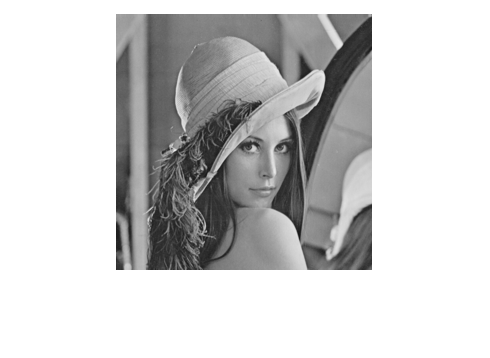

img = imread("../materials/Lena.tif");
[M, N] = size(img);
imshow(img)

shift_img = double(img) .* (-1).^((1:M)' + (1:N));
padd_img = padarray(shift_img,[M, N], 0, "post"); % pad the image to the top left
[P, Q] = size(padd_img);
fft_img = fft2(padd_img);

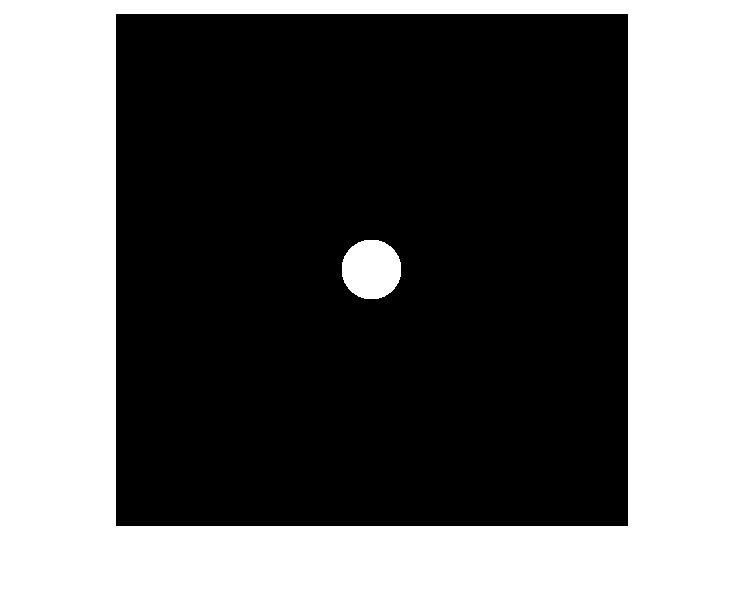

D0 = 30;
ideal_lowpass = zeros(size(padd_img));

% calculate ideal lowpass filter
for x=1:P
    for y=1:Q
        if sqrt((x-P/2)^2+(y-Q/2)^2) < D0
            ideal_lowpass(x, y) = 1;
        end
    end
end

% visualize ideal low pass filter in frequency domain
imshow(ideal_lowpass,[])

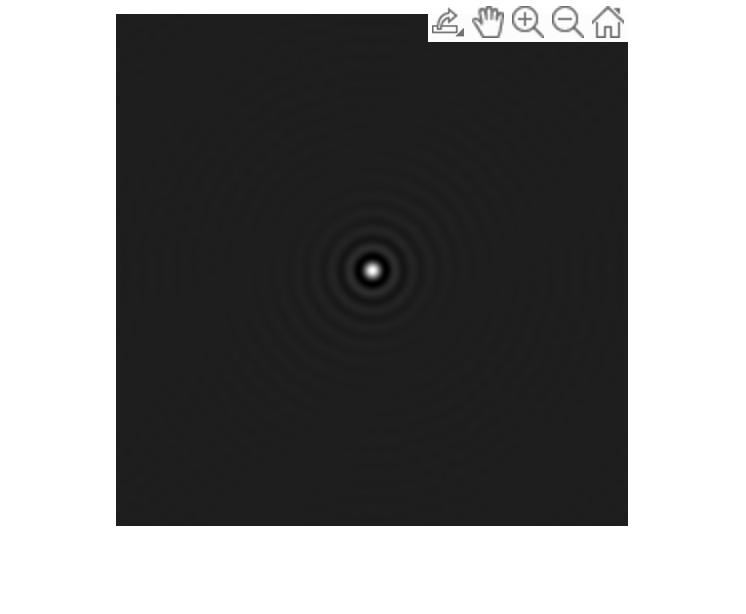


% visualize ideal low pass filter in spatial domain
spatial_filter = real(ifft2(ideal_lowpass));
spatial_filter = spatial_filter.* (-1).^((1:P)' + (1:Q));
imshow(fftshift(spatial_filter), [])

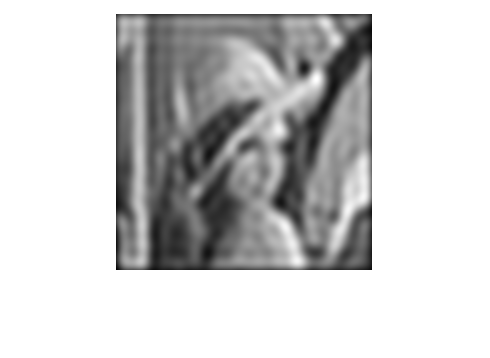


% apply filter in frequency domain
result_freq = fft_img .* ideal_lowpass;
result = ifft2(result_freq);
result = result(1:M, 1:N) .* (-1).^((1:M)' + (1:N));
imshow(real(result), [])

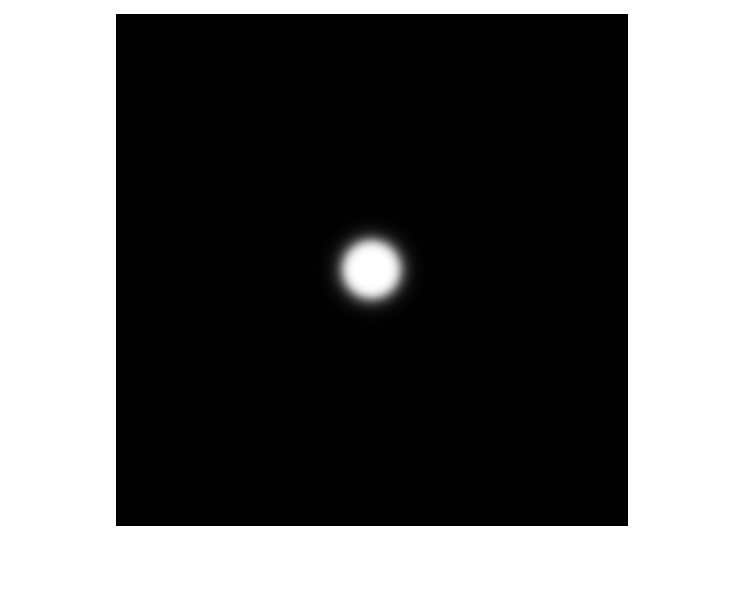

BW_filter = zeros(size(padd_img));

% compute Butterworth low pass filter
for x=1:P
    for y=1:Q
        BW_filter(x, y) = 1 / (1 + (sqrt((x-P/2)^2+(y-Q/2)^2)/D0)^8);
    end
end

% visualize in frequency domain
imshow(BW_filter,[])

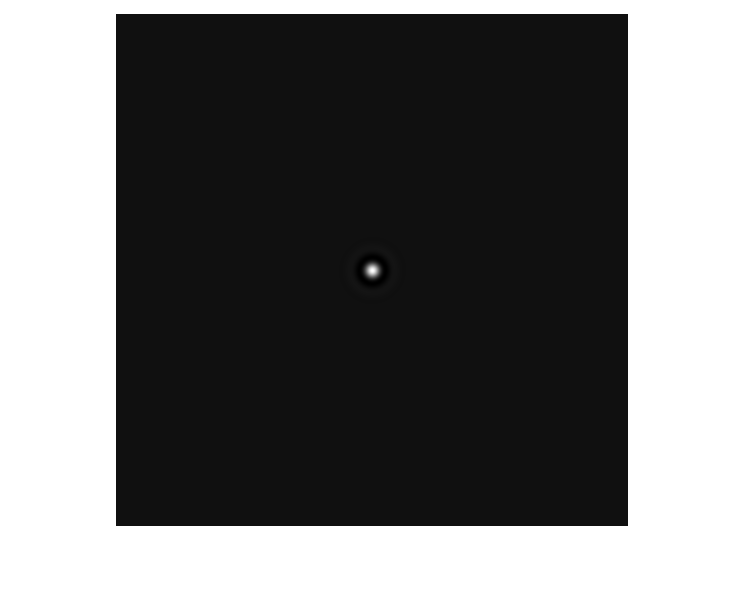


% visualize in spatial domain
spatial_filter = real(ifft2(BW_filter));
spatial_filter = spatial_filter.* (-1).^((1:P)' + (1:Q));
imshow(fftshift(spatial_filter), [])

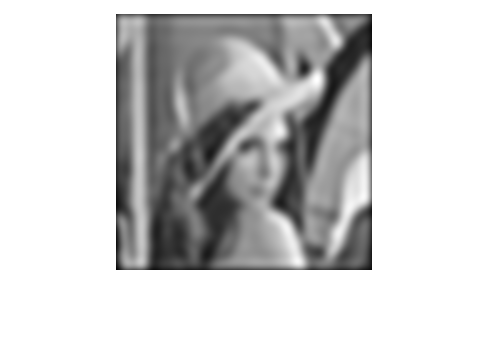


% apply filter in frequency domain
result_freq = fft_img .* BW_filter;
result = ifft2(result_freq);
result = result(1:M, 1:N) .* (-1).^((1:M)' + (1:N));
imshow(real(result), [])